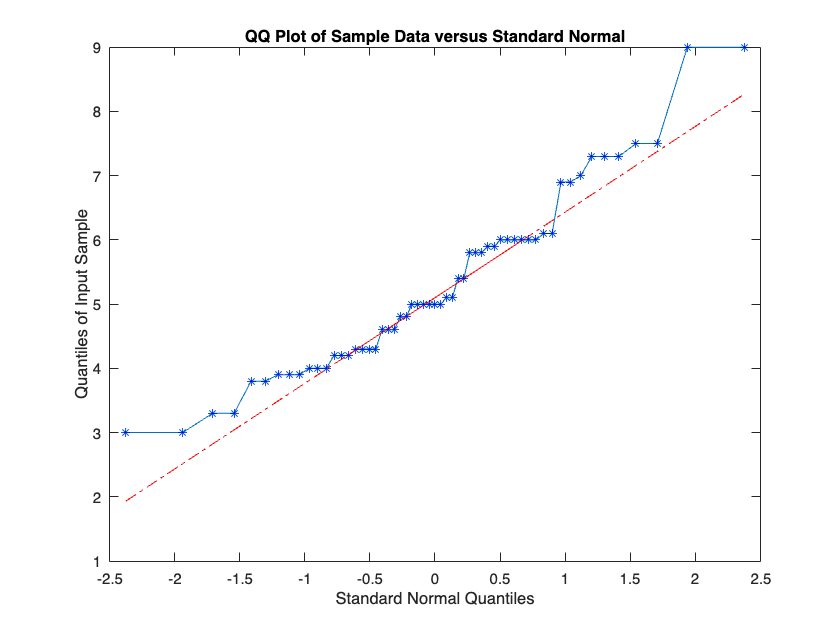

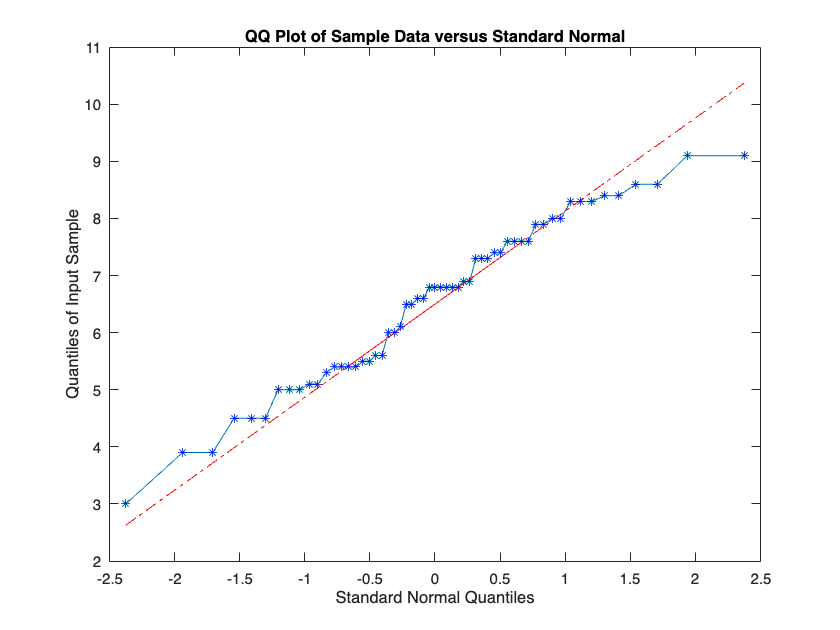

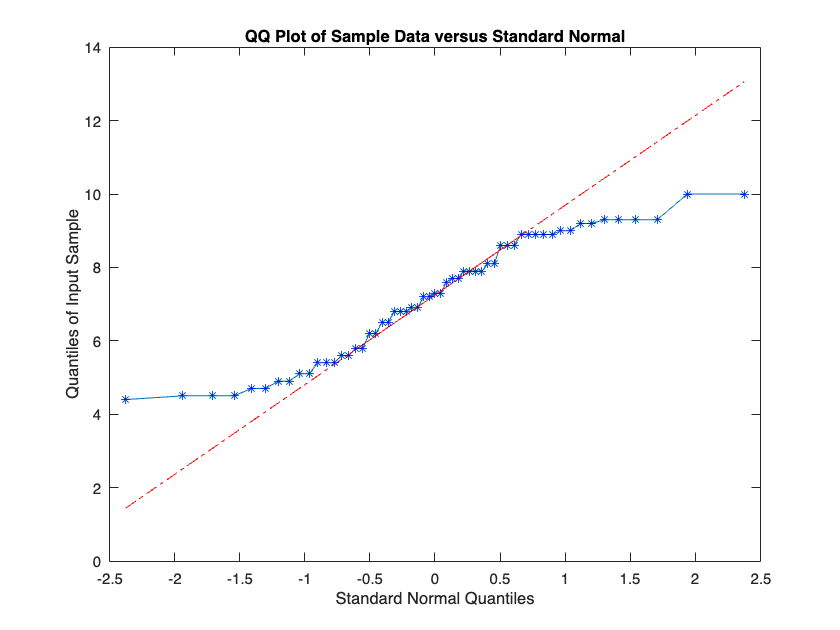

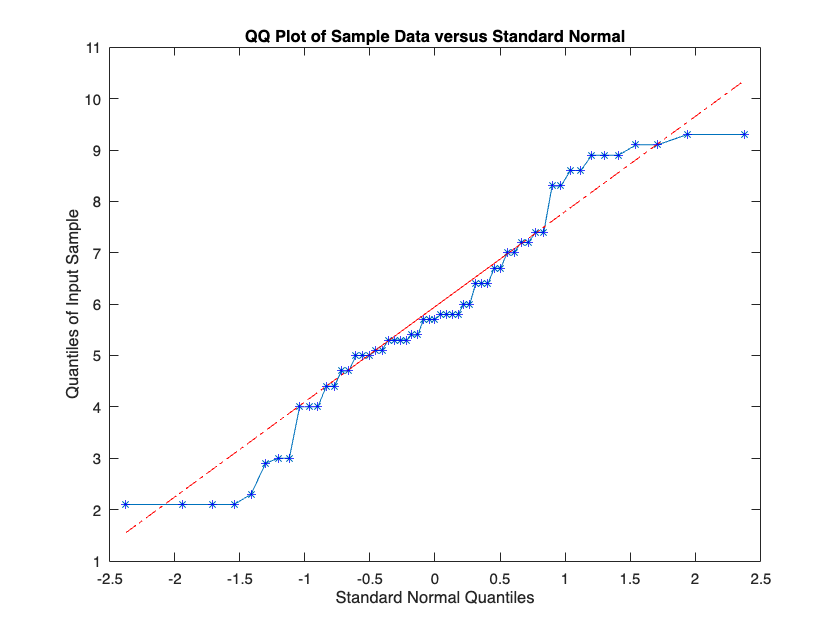

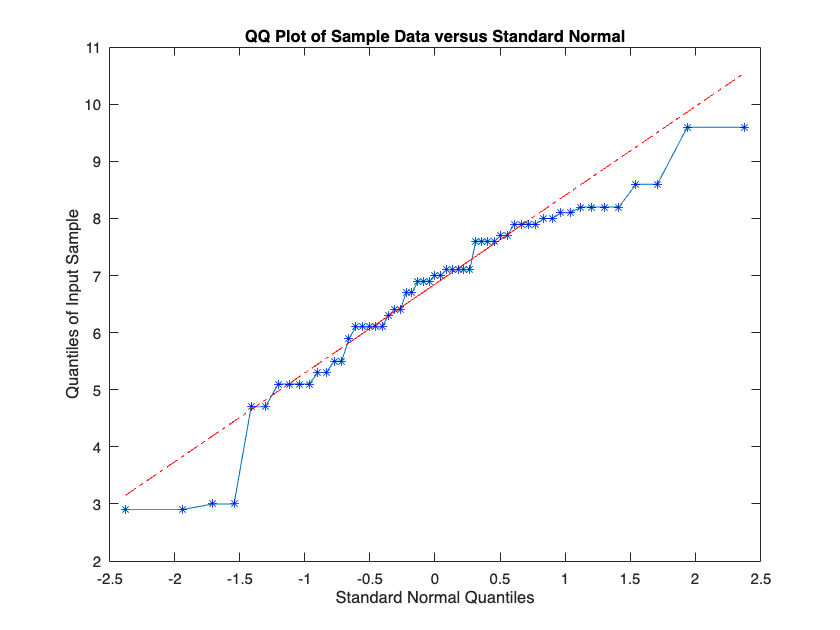

%problem 2

%C
%qqplots --> check normality
data = xlsread('SM22_LabGrades');

for i=1:5
    figure;
    myqqplot(data(:,i));
    hold on;
    qqplot(data(:,i));
    hold off;
end


%correlation_coefficient
q = norminv(((1:length(data))-0.5)/length(data));

for i=1:5
    correlation_coefficient = corr(sort(data(:,i)), q')
end

correlation_coefficient = 0.9766

correlation_coefficient = 0.9883

correlation_coefficient = 0.9730

correlation_coefficient = 0.9822

correlation_coefficient = 0.9713



%check sphericity
variancelab1 = var(data(:,1));
variancelab2 = var(data(:,2));
variancelab4 = var(data(:,3));
variancelab5 = var(data(:,4));
variancelab6 = var(data(:,5));

covtesting(variancelab1, variancelab2);

same variances


covtesting(variancelab1, variancelab4);

same variances


covtesting(variancelab1, variancelab5);

same variances


covtesting(variancelab1, variancelab6);

same variances


covtesting(variancelab2, variancelab4);

same variances


covtesting(variancelab2, variancelab5);

same variances


covtesting(variancelab2, variancelab6);

same variances


covtesting(variancelab4, variancelab5);

same variances


covtesting(variancelab4, variancelab6);

same variances


covtesting(variancelab5, variancelab6);

same variances


n = 57

n = 57

g = 5

g = 5


%D test hypothesis
meanlab1 = mean(data(:,1))

meanlab1 = 5.2842

meanlab2 = mean(data(:,2))

meanlab2 = 6.5526

meanlab4 = mean(data(:,3))

meanlab4 = 7.1860

meanlab5 = mean(data(:,4))

meanlab5 = 5.8316

meanlab6 = mean(data(:,5))

meanlab6 = 6.6860

means = [meanlab1, meanlab2, meanlab4, meanlab5, meanlab6];

overallmean = mean(alldata)

overallmean = 6.3081


rowmeans = [];
for i=1:n
    rowmeans(i) = mean(data(i,:));
end

SSw = mySSw(data, means,n,g);

SSw = 745.0586


SSsubj = mySSsubj(data, rowmeans, overallmean, n, g);

SSsubj = 260.8074


SSres = SSw - SSsubj;

SSres = 484.2512


SSb = mySSb(data, means, overallmean, n, g);

SSb = 128.1728


mystat = (SSb/(g-1))/(SSres/((n-1)*(g-1)));

mystat = 14.8222


fcrit = finv(0.99, g-1, n-g+1);

fcrit = 3.6954


%postHoc
MSw= SSw/(g*(n-1));
postHoc(meanlab1, meanlab2, length(data(:,1)), length(data(:,2)), MSw, 0.01, g, n);

dont have enough evidence to reject


postHoc(meanlab1, meanlab4, length(data(:,1)), length(data(:,3)), MSw, 0.01, g, n);

dont have enough evidence to reject


postHoc(meanlab1, meanlab5, length(data(:,1)), length(data(:,4)), MSw, 0.01, g, n);

dont have enough evidence to reject


postHoc(meanlab1, meanlab6, length(data(:,1)), length(data(:,5)), MSw, 0.01, g, n);

dont have enough evidence to reject


postHoc(meanlab2, meanlab4, length(data(:,2)), length(data(:,3)), MSw, 0.01, g, n);

dont have enough evidence to reject


postHoc(meanlab2, meanlab5, length(data(:,2)), length(data(:,4)), MSw, 0.01, g, n);

dont have enough evidence to reject


postHoc(meanlab2, meanlab6, length(data(:,2)), length(data(:,5)), MSw, 0.01, g, n);

dont have enough evidence to reject


postHoc(meanlab4, meanlab5, length(data(:,3)), length(data(:,4)), MSw, 0.01, g, n);

reject


postHoc(meanlab4, meanlab6, length(data(:,3)), length(data(:,5)), MSw, 0.01, g, n);

dont have enough evidence to reject


postHoc(meanlab5, meanlab6, length(data(:,4)), length(data(:,5)), MSw, 0.01, g, n);

dont have enough evidence to reject


%E Compute confidence intervals for the difference of the average lab marks (for all pairs of labs). Indicate whether these intervals confirm your findings in (d).
[from, to] = myCI(meanlab1, meanlab2, n, g, SSres)

from = -2.3569

to = 3.0854

[from, to] = myCI(meanlab1, meanlab4, n, g, SSres)

from = -2.9902

to = 2.4520

[from, to] = myCI(meanlab1, meanlab5, n, g, SSres)

from = -1.6358

to = 3.8064

[from, to] = myCI(meanlab1, meanlab6, n, g, SSres)

from = -2.4902

to = 2.9520


[from, to] = myCI(meanlab2, meanlab4, n, g, SSres)

from = -1.7218

to = 3.7205

[from, to] = myCI(meanlab2, meanlab5, n, g, SSres)

from = -0.3674

to = 5.0748

[from, to] = myCI(meanlab2, meanlab6, n, g, SSres)

from = -1.2218

to = 4.2205


[from, to] = myCI(meanlab4, meanlab5, n, g, SSres)

from = 0.2659

to = 5.7082

[from, to] = myCI(meanlab4, meanlab6, n, g, SSres)

from = -0.5884

to = 4.8538


[from, to] = myCI(meanlab5, meanlab6, n, g, SSres)

from = -1.9428

to = 3.4994

%some functions used:

function myqqplot(x)
    %quantiles
    q = norminv(((1:length(x))-0.5)/length(x));
    plot(q, sort(x), '-*');
end


function mychi2plot(x)
    meanX = mean(x')'
    s = cov(x');
    dj = [];
    qc = chi2inv(((1:length(x))-0.5)/length(x),2);
    for j=1: length(x)
        dj = [dj, (x(:,j) - meanX)'*inv(s)*(x(:,j) - meanX)];
    end
    figure;
    plot(qc, sort(dj), '*');
    hold on;
    plot(qc,qc,'r--'); %slope 1
    hold off;
end


function SSw = mySSw(data, means,n,g)
    SSw = 0;
    for i = 1:g
        for j = 1:n
            SSw = SSw + (data(j, i) - means(i))^2;
        end
    end
end

function SSsubj = mySSsubj(data, rowmeans, overallmean, n, g)
    SSsubj = 0;
    for j = 1:n
        SSsubj = SSsubj + g * (rowmeans(j) - overallmean)^2;
    end
end

function SSb = mySSb(data, means, overallmean, n, g)
    SSb = 0;
    for j = 1:g
        SSb = SSb + n * (means(j) - overallmean)^2;
    end
end

function covtesting(variance1, variance2)
    div =  variance1/variance2;
    if div <1/4 || div>4
        disp("diff variances");
    else
        disp("same variances");
    end
end

function [low, high] = myCI(mean1, mean2, n, g, SSres)
    fcrit = sqrt((((n-1)*(g-1))/(n-g+1))*finv(0.99, g-1, n-g+1));
    low = mean1 - mean2 - fcrit * sqrt(SSres/((n-1)*(g-1))*(1/n+1/n));
    high = mean1 - mean2 + fcrit * sqrt(SSres/(n-1)*(g-1)*(1/n+1/n));
    
end


function postHoc(mean1, mean2, n1, n2, MSw, alpha, g, n)
    statistic = (mean1-mean2)/sqrt(((1/n1)+(1/n2))*MSw);
    tcrit = tinv(1-alpha/(g*(g-1)), n-g);
    if tcrit < statistic
        disp('reject');
    else
        disp('dont have enough evidence to reject');
    end
end









